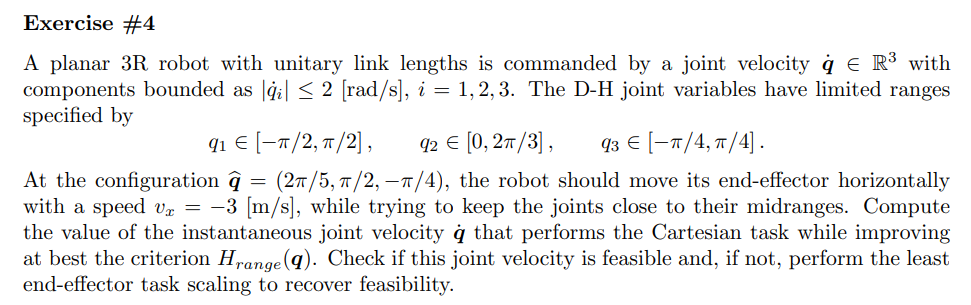

syms q1 q2 q3 real;
q=[q1;q2;q3];

In questo esercizio si sta lavorando un robot 3R (n=3) e la task speficata è nel piano, in particolare si vuole regolare la posizione dlel' end effector nel piano quindi m=2.

Inoltre i vincoli non sono imposti come hard constraint ma si usa una funzione obiettino nel tentativo di fare del nostro meglio per cui SNS non è idoneo. Scelgiamo di risolvere il problema tramite la tecinca di Project gradient che fa parte dei Null-Space Methods.

Sappiamo che la soluzione a questo problema è data da:    $\dot{q}=J^\#\dot{r}+(I-J^\#J)\dot{q_0}$    dove $\dot{q_0}=\nabla_qH(q)$   quindi la soluzione è:


$$\dot{q}=J^\#\dot{r}+(I-J^\#J)\nabla_qH(q)$$


In particular we try to keep the joints close to their midranges, so we're considering the objective function $H_{range}(q)$ given by:


$$H_{range}(q) = \frac{1}{2N}\sum^N_{i=1}\left( \frac{q_i-\bar{q_i}}{q_{M,i}-q_{m,i}}\right)^2$$


**so we have to consider that we're dealing with a minimum problem and so the formula that gives the desidered joint velocities becomes:**


$$\dot{q}=J^\#\dot{r}-(I-J^\#J)\nabla_qH_{range}(q)$$


So the first thing that we have to define is the vector $\dot{r}=(\dot{r}_x \quad \dot{r}_y)^T$

r_dot=[0;1]

r_dot =      0
     1


Now we have to evaluate the Jacobian in the given configuration, Fist of all we have to consider the direct kinematic of the 3R-planar robot that is:

Px=cos(q1)+cos(q2)+cos(q3);
Py=sin(q1)+sin(q2)+sin(q3);
P=[Px;Py]

$$P = \left(\begin{array}{c} \cos\left(q_{1}\right)+\cos\left(q_{2}\right)+\cos\left(q_{3}\right)\\ \sin\left(q_{1}\right)+\sin\left(q_{2}\right)+\sin\left(q_{3}\right) \end{array}\right)$$

J_sym=simplify(jacobian(P,q))

$$J\_sym = \left(\begin{array}{ccc} -\sin\left(q_{1}\right) & -\sin\left(q_{2}\right) & -\sin\left(q_{3}\right)\\ \cos\left(q_{1}\right) & \cos\left(q_{2}\right) & \cos\left(q_{3}\right) \end{array}\right)$$

J=round(vpa(subs(J_sym,q,[0;pi/2;0])),4)

$$J = \left(\begin{array}{ccc} 0 & -1.0 & 0\\ 1.0 & 0 & 1.0 \end{array}\right)$$

Now we have to consider the objective function:

LEt's evaluate the mid points of the joint ranges using : $\frac{q_{M,i}-q_{m,i}}{2}$

%q1_bar=(-pi/2+pi/2)/2;
%q2_bar=((2*pi)/3+0)/2;
%q3_bar=(pi/4-pi/4)/2;

Now let' s evaluate       $H_{range}(q) = \frac{1}{2N}\sum^N_{i=1}\left( \frac{q_i-\bar{q_i}}{q_{M,i}-q_{m,i}}\right)^2$   occhio che è tutto al quadrato, anche il denominatore. ed è meglio farlo a mano su un foglio:

%H_range=1/6*( (q1^2)/((pi)^2) + ((q2-(pi/3))^2)/(((2*pi)/3)^2)  + (q3^2)/((pi/2)^2)  )
%Nabla_H_range_sym=vpa([diff(H_range,q1);diff(H_range,q2);diff(H_range,q3)])

a=[cos(q1)+cos(q2);sin(q1)+sin(q2)]

$$a = \left(\begin{array}{c} \cos\left(q_{1}\right)+\cos\left(q_{2}\right)\\ \sin\left(q_{1}\right)+\sin\left(q_{2}\right) \end{array}\right)$$

aa=jacobian(a,q)

$$aa = \left(\begin{array}{ccc} -\sin\left(q_{1}\right) & -\sin\left(q_{2}\right) & 0\\ \cos\left(q_{1}\right) & \cos\left(q_{2}\right) & 0 \end{array}\right)$$

b=[0.3536;1.6464]

b =     0.3536
    1.6464


a_bar=subs(a,[q1,q2],[0,pi/2])

$$a\_bar = \left(\begin{array}{c} 1\\ 1 \end{array}\right)$$

%H_obs=
norm=round(double(sqrt(transpose((a_bar-b))*(a_bar-b))),4)

norm = 0.9141

Jaa=subs(aa,[q1,q2],[0,pi/2]);
transpose(Jaa)

$$ans = \left(\begin{array}{cc} 0 & 1\\ -1 & 0\\ 0 & 0 \end{array}\right)$$

round(double(a_bar-b),4)

ans =     0.6464
   -0.6464


nabla_H_dist=round(double((1/2)*1/norm*transpose(Jaa)*(a_bar-b)),4)

nabla_H_dist =    -0.3536
   -0.3536
         0


Remember that we have to evaluate  $\nabla_qH_{range}(q)$ in the desidered configuration, so:

%Nabla_H_range=round(vpa(subs(Nabla_H_range_sym,q,[2*pi/5;pi/2;-pi/4])),4)

Now we have all teh ingredients in order to evaluate   $\dot{q}=J^\#\dot{r}-(I-J^\#J)\nabla_qH_{range}(q)$   in the given configuration and so let's do it:

q_dot=round(pinv(J)*r_dot-(eye(3)-pinv(J)*J)*nabla_H_dist,4)

$$q\_dot = \left(\begin{array}{c} 0.6768\\ 0\\ 0.3232 \end{array}\right)$$

Now note that each joint has bound in velocity given by $q_i\leq|2| \ \left[ \frac{rad}{s}\right]$ and we can see that the first joint exced this limit so we have to scale all the joints velocity in order to have a feasible velocity:

When we scale the velocity we consider only the velocity obtained by $\dot{q}=J^\#\dot{r}$ because this is the one that satisfy the task velocity. The other component given by $-(I-J^\#J)\nabla_qH_{range}(q)$ is used only to minimize the cost function so we wnat to preserv it.

So at first let's evaluate the two contribute separately:

q_r_dot=round(pinv(J)*r_dot,4)

$$q\_r\_dot = \left(\begin{array}{c} 0.5\\ 0\\ 0.5 \end{array}\right)$$

q_n_dot=round(-(eye(3)-pinv(J)*J)*Nabla_H_range,4)

$$q\_n\_dot = \left(\begin{array}{c} -0.0742\\ 0\\ 0.0742 \end{array}\right)$$

and so we do the scale in the following way:

$\dot{r}=K\dot{r} \to \quad \dot{q}\to K\dot{q}_r+\dot{q}_n$     the first joint exced the ranges so  $\to K \dot{q}_{k,1}+\dot{q}_{n,1} = \dot{q}_{max} \to K^*=\frac{\dot{q}_{max}-\dot{q}_{n,1}}{\dot{q}_{r,1}}=\frac{2+0.0437}{2.1076}=0.9697$

so we need to compute $\dot{q}_{scaled}=K^*\dot{q}_r+\dot{q}_n$

K_star=0.9697;
q_dot_scaled=round(K_star*q_r_dot+q_n_dot,4)

$$q\_dot\_scaled = \left(\begin{array}{c} 0.4106\\ 0\\ 0.559 \end{array}\right)$$

As we cam see these joint velocities respect the bounds. And the obtained task velocity is given by    $\dot{r}_{scaled}=K^*\dot{r}=J\dot{q}_s$

r_scaled_dot=round(J*q_dot_scaled,3)

$$r\_scaled\_dot = \left(\begin{array}{c} 0\\ 0.97 \end{array}\right)$$